# 1

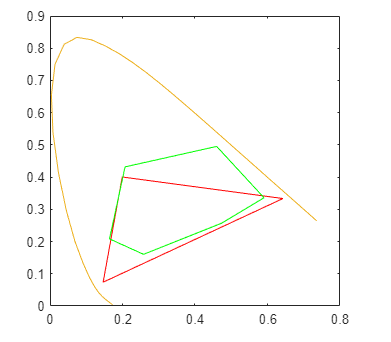

plot_chrom(XYZdell, 'red')
plot_chrom(XYZinkjet, 'green')

# 2

## 2.1

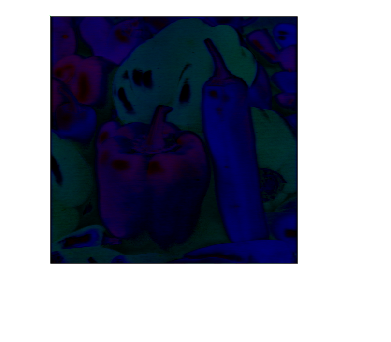

t = Tiff('peppers_color.tif','r');
t2 = Tiff('peppers_gray.tif','r');
pc = read(t);
pg = read(t2);

imshow(pg)
imshow(pc)
imshow(pc-pg)
imshow(pg-pc)


mysnr(pg, pc-pg)

ans = -0.7516

mysnr(pg, pg-pc)

ans = -1.6483

### 2.1.1

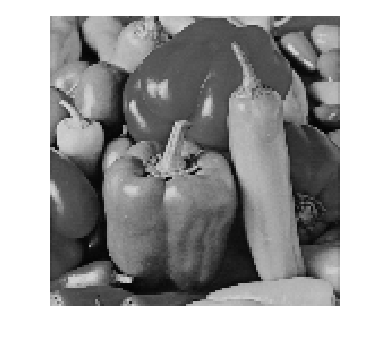

pg_resized1 = imresize(imresize(pg,0.25,'nearest'),4,'nearest');
imshow(pg_resized1)

mysnr(pg, pg-pg_resized1)

ans = 10.4676

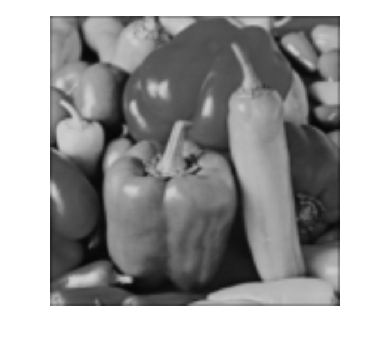


pg_resized2 = imresize(imresize(pg,0.25,'bilinear'),4,'bilinear');
imshow(pg_resized2)

mysnr(pg, pg-pg_resized2)

ans = 9.9089

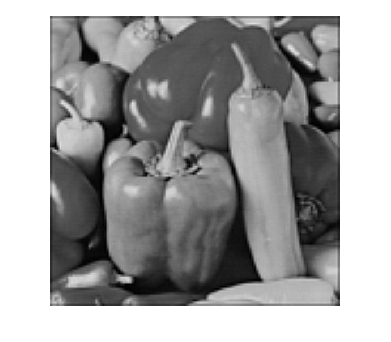

pg_resized2_sharpen = imsharpen(pg_resized2,'Radius',2,'Amount',2);
imshow(pg_resized2_sharpen)

mysnr(pg, pg-pg_resized2_sharpen)

ans = 10.7292

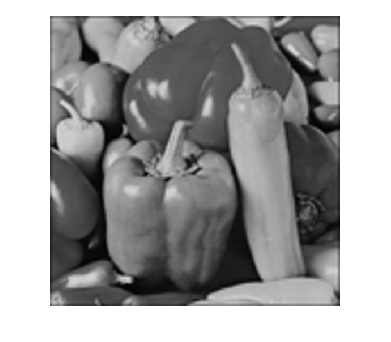


pg_resized3 = imresize(imresize(pg,0.25,'bicubic'),4,'bicubic');
imshow(pg_resized3)

mysnr(pg, pg-pg_resized3)

ans = 10.8879

### 2.1.2

pg = im2double(pg)

pg =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.7451    0.5843    0.6078    0.6118    0.6353    0.6510    0.6588    0.6588    0.6588    0.6588    0.6667    0.6745    0.6824    0.6784    0.6784    0.6824    0.6784    0.6706    0.6549    0.6314    0.6235    0.6275    0.6039    0.5804    0.5725    0.5569    0.5490    0.5333    0.5373    0.5255    0.5098    0.5098    0.5176    0.5176    0.5098    0.5176    0.5216    0.5020    0.5059    0.5020    0.4824    0.4627    0.4275    0.3961    0.3608    0.3294    0.2902    0.2549    

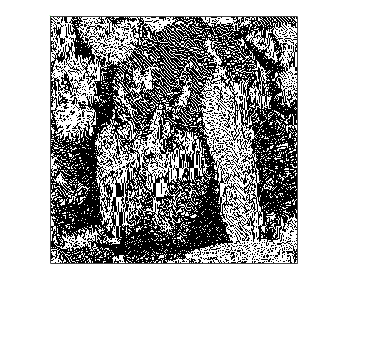


pg_thres = pg >= 0.5;
imshow(pg_thres)
pg_dither = dither(pg);
imshow(pg_dither)


mysnr(pg, pg - double(pg_thres))

ans = 2.9721

mysnr(pg, pg - double(pg_dither))

ans = 0.4112

## 2.2

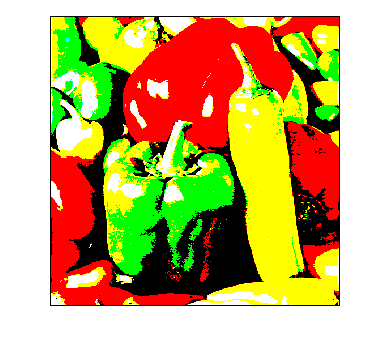

img(:,:,1) = (pc(:,:,1)/256) >= 0.5;
img(:,:,2) = (pc(:,:,2)/256) >= 0.5;
img(:,:,3) = (pc(:,:,3)/256) >= 0.5;

img1(:,:,1) = dither(im2double(pc(:,:,1)));
img1(:,:,2) = dither(im2double(pc(:,:,2)));
img1(:,:,3) = dither(im2double(pc(:,:,3)));

imshow(im2double(img))

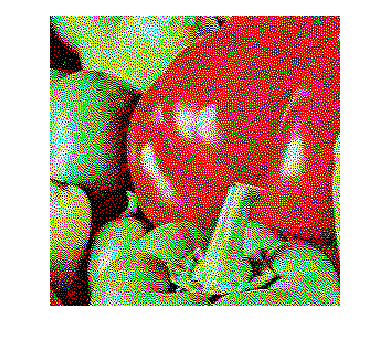

imshow(im2double(img1))


img_lab=rgb2lab(im2uint8(img));
img1_lab=rgb2lab(im2uint8(img1));

pc_lab=rgb2lab(pc);

dE = euclidean_distance_lab_nxnx3(img_lab, pc_lab);
dE1 = euclidean_distance_lab_nxnx3(img1_lab, pc_lab);
max(max(dE))

ans = 120.1919

mean(mean(dE))

ans = 50.1577

max(max(dE1))

ans = 203.6272

mean(mean(dE1))

ans = 72.8423

# 3

snr_filter(double(pg_thres), pg - double(pg_thres))

ans = 5.8391

snr_filter(double(pg_dither), pg - double(pg_dither))

ans = 13.5280


f = MFTsp(15,0.0847,500);

% thresholded picture
img_hvs(:,:,1) = conv2(im2uint8(img(:,:,1)),f,'same');
img_hvs(:,:,2) = conv2(im2uint8(img(:,:,2)),f,'same');
img_hvs(:,:,3) = conv2(im2uint8(img(:,:,3)),f,'same');

img_hvs(:,:,1) = (img_hvs(:,:,1) > 0) .* img_hvs(:,:,1);
img_hvs(:,:,2) = (img_hvs(:,:,2) > 0) .* img_hvs(:,:,2);
img_hvs(:,:,3) = (img_hvs(:,:,3) > 0) .* img_hvs(:,:,3);

img_hvs_lab = rgb2lab((img_hvs)/256);

dE = euclidean_distance_lab_nxnx3(img_hvs_lab, pc_lab);

max(max(dE))

ans = 105.5223

mean(mean(dE))

ans = 47.7457


% Dithered picture
img_hvs(:,:,1) = conv2(im2uint8(img1(:,:,1)),f,'same');
img_hvs(:,:,2) = conv2(im2uint8(img1(:,:,2)),f,'same');
img_hvs(:,:,3) = conv2(im2uint8(img1(:,:,3)),f,'same');

img_hvs(:,:,1) = (img_hvs(:,:,1) > 0) .* img_hvs(:,:,1);
img_hvs(:,:,2) = (img_hvs(:,:,2) > 0) .* img_hvs(:,:,2);
img_hvs(:,:,3) = (img_hvs(:,:,3) > 0) .* img_hvs(:,:,3);

img_hvs_lab = rgb2lab((img_hvs)/256);

dE = euclidean_distance_lab_nxnx3(img_hvs_lab, pc_lab);

max(max(dE))

ans = 82.8663

mean(mean(dE))

ans = 20.1190

# 4

## 4.1

pc_r1 = imresize(imresize(pc,0.25,'nearest'),4,'nearest');
pc_r2 = imresize(imresize(pc,0.25,'bilinear'),4,'bilinear');
pc_r3 = imresize(imresize(pc,0.25,'bicubic'),4,'bicubic');

pc_r1_xyz = rgb2xyz(pc_r1);
pc_r2_xyz = rgb2xyz(pc_r2);
pc_r3_xyz = rgb2xyz(pc_r3);

ls =  [95.05, 100, 108.9]

ls =    95.0500  100.0000  108.9000



im_format = 'xyz'

im_format = 'xyz'


ppi = 91.79

ppi = 91.7900

d = 24

d = 24


im_scielab_n = scielab(ppi*d*1.5574,rgb2xyz(pc), pc_r1_xyz, ls, im_format)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


im_scielab_n =     0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0514    0.0514    0.0514    0.0513    0.0513    0.0513    0.0512    0.0512    0.0511    0.0511    0.0510    0.0510    0.0509    0.0508    0.0508    0.0507    0.0506    0.0506    0.0505    0.0504    0.0503    0.0502    0.0502    0.0501    0.0500    0.0499    0.0498    0.0497    0.0496    0.0495    0.0494    0.0493    0.0492    0.0490    0.0489    0.0488    0.0487    0.0486    0.0485    0.0483    0.0482
    0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0515    0.0514    0.0514    0.0514    0.0513    0.0513    0.0513    0.0512    0.0512    0.0511    0.0511    0.0510    0.0510    0.0509    0.0508    0.0508    0.0507    0.0506    0.0506    0.0505    0.0504    0.0503    0.0502    0.0501    0.0501    0.0500    0.0499    0.0498    0.0497    0.0496    0.0495    0.0494    0.0493    0.0491    0.0490    0.0489    0.0488    0.0487    0.0486    0.0484    

im_scielab_bl = scielab(ppi*d*1.5574,rgb2xyz(pc), pc_r2_xyz, ls, im_format)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


im_scielab_bl =     0.1410    0.1410    0.1410    0.1410    0.1410    0.1410    0.1409    0.1409    0.1408    0.1407    0.1407    0.1406    0.1405    0.1404    0.1403    0.1402    0.1401    0.1400    0.1398    0.1397    0.1395    0.1394    0.1392    0.1390    0.1389    0.1387    0.1385    0.1383    0.1381    0.1379    0.1377    0.1374    0.1372    0.1370    0.1367    0.1365    0.1363    0.1360    0.1357    0.1355    0.1352    0.1349    0.1347    0.1344    0.1341    0.1338    0.1335    0.1332    0.1329    0.1326
    0.1410    0.1410    0.1410    0.1410    0.1410    0.1410    0.1409    0.1409    0.1408    0.1407    0.1407    0.1406    0.1405    0.1404    0.1403    0.1402    0.1401    0.1400    0.1398    0.1397    0.1395    0.1394    0.1392    0.1390    0.1389    0.1387    0.1385    0.1383    0.1381    0.1379    0.1377    0.1374    0.1372    0.1370    0.1367    0.1365    0.1363    0.1360    0.1357    0.1355    0.1352    0.1349    0.1347    0.1344    0.1341    0.1338    0.1335    0.1332   

im_scielab_bc = scielab(ppi*d*1.5574,rgb2xyz(pc), pc_r3_xyz, ls, im_format)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


im_scielab_bc =     0.0981    0.0981    0.0980    0.0980    0.0980    0.0980    0.0979    0.0978    0.0978    0.0977    0.0976    0.0975    0.0974    0.0973    0.0972    0.0971    0.0970    0.0968    0.0967    0.0965    0.0964    0.0962    0.0960    0.0958    0.0956    0.0954    0.0952    0.0950    0.0948    0.0946    0.0943    0.0941    0.0938    0.0936    0.0933    0.0931    0.0928    0.0925    0.0922    0.0920    0.0917    0.0914    0.0911    0.0908    0.0905    0.0901    0.0898    0.0895    0.0892    0.0889
    0.0981    0.0981    0.0980    0.0980    0.0980    0.0979    0.0979    0.0978    0.0978    0.0977    0.0976    0.0975    0.0974    0.0973    0.0972    0.0971    0.0970    0.0968    0.0967    0.0965    0.0964    0.0962    0.0960    0.0958    0.0956    0.0954    0.0952    0.0950    0.0948    0.0946    0.0943    0.0941    0.0938    0.0936    0.0933    0.0931    0.0928    0.0925    0.0922    0.0920    0.0917    0.0914    0.0911    0.0908    0.0905    0.0901    0.0898    0.0895   


mean(mean(im_scielab_n))

ans = 0.0225

mean(mean(im_scielab_bl))

ans = 0.0881

mean(mean(im_scielab_bc))

ans = 0.0460

## 4.2

sampPerDeg = ppi*d*1.5574;
SCIELAB_STD(sampPerDeg, c1)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


ans = 0.0059

SCIELAB_STD(sampPerDeg, c2)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


ans = 0.0037

SCIELAB_STD(sampPerDeg, c3)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


ans = 0.0058

SCIELAB_STD(sampPerDeg, c4)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


ans = 0.0080

SCIELAB_STD(sampPerDeg, c5)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


ans = 0.0048

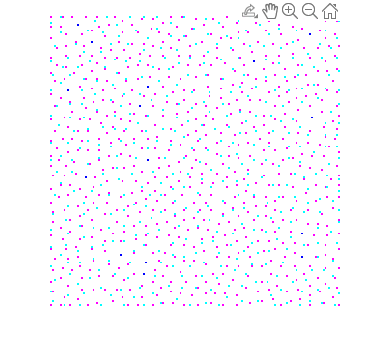


imshow(c1)

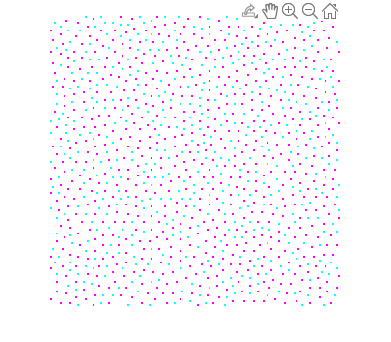

imshow(c2)

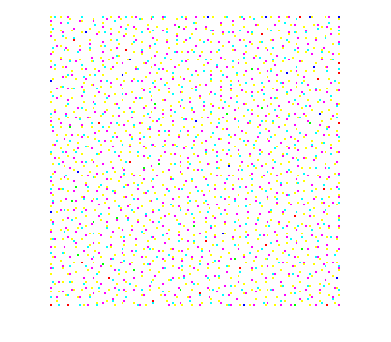

imshow(c3)

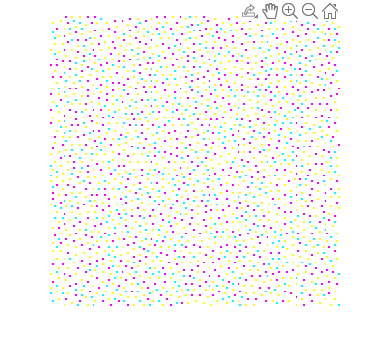

imshow(c4)

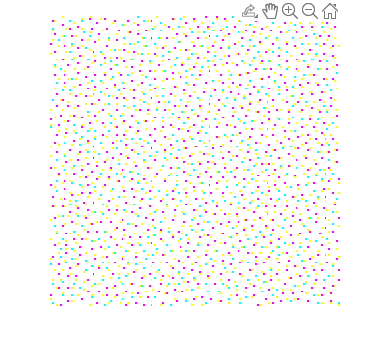

imshow(c5)

# 5

## a

im2double(pg)

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.7451    0.5843    0.6078    0.6118    0.6353    0.6510    0.6588    0.6588    0.6588    0.6588    0.6667    0.6745    0.6824    0.6784    0.6784    0.6824    0.6784    0.6706    0.6549    0.6314    0.6235    0.6275    0.6039    0.5804    0.5725    0.5569    0.5490    0.5333    0.5373    0.5255    0.5098    0.5098    0.5176    0.5176    0.5098    0.5176    0.5216    0.5020    0.5059    0.5020    0.4824    0.4627    0.4275    0.3961    0.3608    0.3294    0.2902    0.2549   

d1 = distort1(im2double(pg))

d1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.8451    0.4843    0.7078    0.5118    0.7353    0.5510    0.7588    0.5588    0.7588    0.5588    0.7667    0.5745    0.7824    0.5784    0.7784    0.5824    0.7784    0.5706    0.7549    0.5314    0.7235    0.5275    0.7039    0.4804    0.6725    0.4569    0.6490    0.4333    0.6373    0.4255    0.6098    0.4098    0.6176    0.4176    0.6098    0.4176    0.6216    0.4020    0.6059    0.4020    0.5824    0.3627    0.5275    0.2961    0.4608    0.2294    0.3902    0.1549    

d2 = distort2(im2double(pg))

d2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.8451    0.6843    0.7078    0.7118    0.7353    0.7510    0.7588    0.7588    0.7588    0.7588    0.7667    0.7745    0.7824    0.7784    0.7784    0.7824    0.7784    0.7706    0.7549    0.7314    0.7235    0.7275    0.7039    0.6804    0.6725    0.6569    0.6490    0.6333    0.6373    0.6255    0.6098    0.6098    0.6176    0.6176    0.6098    0.6176    0.6216    0.6020    0.6059    0.6020    0.5824    0.5627    0.5275    0.4961    0.4608    0.4294    0.3902    0.3549    


mysnr(im2double(pg), im2double(pg) - d1)

ans = 13.4643

mysnr(im2double(pg), im2double(pg) - d2)

ans = 13.4643


[s1,s1_map]=ssim(d1,im2double(pg))

s1 = 0.2466

s1_map =     0.9879    0.9861    0.9835    0.9815    0.9809    0.9813    0.9818    0.9821    0.9823    0.9824    0.9826    0.9828    0.9831    0.9833    0.9834    0.9834    0.9833    0.9830    0.9826    0.9819    0.9811    0.9803    0.9795    0.9786    0.9777    0.9766    0.9756    0.9746    0.9738    0.9731    0.9725    0.9721    0.9719    0.9718    0.9716    0.9715    0.9712    0.9708    0.9701    0.9694    0.9683    0.9669    0.9645    0.9608    0.9553    0.9476    0.9373    0.9255    0.9163    0.9151
    0.9869    0.9829    0.9764    0.9706    0.9682    0.9685    0.9692    0.9698    0.9700    0.9702    0.9704    0.9709    0.9713    0.9716    0.9718    0.9717    0.9714    0.9710    0.9702    0.9692    0.9678    0.9664    0.9650    0.9636    0.9620    0.9604    0.9587    0.9571    0.9557    0.9546    0.9538    0.9532    0.9529    0.9527    0.9523    0.9519    0.9513    0.9505    0.9494    0.9481    0.9464    0.9442    0.9408    0.9357    0.9278    0.9165    0.9013    0.8831    0.8677

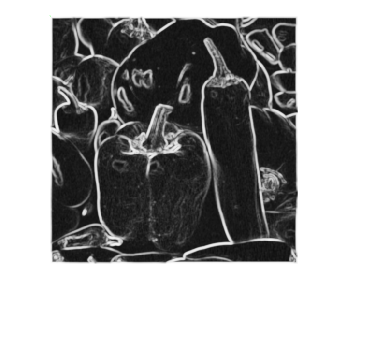

imshow(s1_map)

[s1,s1_map2]=ssim(d2,im2double(pg))

s1 = 0.8550

s1_map2 =     0.9821    0.9809    0.9796    0.9788    0.9788    0.9793    0.9799    0.9803    0.9804    0.9806    0.9807    0.9809    0.9812    0.9814    0.9816    0.9816    0.9814    0.9812    0.9807    0.9800    0.9792    0.9784    0.9775    0.9766    0.9756    0.9745    0.9735    0.9725    0.9717    0.9710    0.9705    0.9701    0.9699    0.9698    0.9696    0.9694    0.9692    0.9687    0.9681    0.9673    0.9663    0.9648    0.9624    0.9587    0.9532    0.9457    0.9360    0.9254    0.9175    0.9165
    0.9823    0.9811    0.9798    0.9790    0.9789    0.9795    0.9800    0.9804    0.9805    0.9806    0.9808    0.9810    0.9813    0.9815    0.9816    0.9816    0.9814    0.9811    0.9806    0.9800    0.9791    0.9783    0.9774    0.9765    0.9756    0.9745    0.9735    0.9726    0.9718    0.9711    0.9707    0.9703    0.9701    0.9700    0.9698    0.9695    0.9692    0.9687    0.9680    0.9672    0.9662    0.9648    0.9626    0.9593    0.9543    0.9472    0.9380    0.9275    0.919

% imshow(s1_map2)


## b

% distortion
dist1 = im2double(pg)+0.2*(rand(size(im2double(pg)))-0.5)

dist1 =     0.0296   -0.0394   -0.0681    0.0467    0.0118    0.0882    0.0416   -0.0479   -0.0754   -0.0096    0.0208    0.0931    0.0644    0.0269    0.0481    0.0685    0.0361    0.0620   -0.0947   -0.0702    0.0542   -0.0590   -0.0720    0.0744   -0.0530    0.0118    0.0402    0.0916   -0.0803   -0.0119    0.0478   -0.0970    0.0993   -0.0358   -0.0973    0.0266    0.0934   -0.0582    0.0566   -0.0024    0.0991    0.0650    0.0865   -0.0240    0.0529    0.0629   -0.0231    0.0562    0.0697    0.0570
    0.0660    0.7362    0.5004    0.6532    0.5157    0.6997    0.5514    0.6523    0.6814    0.7096    0.5859    0.7401    0.6498    0.6409    0.5888    0.6281    0.6922    0.6238    0.6121    0.6267    0.6248    0.5256    0.5377    0.5846    0.6742    0.5870    0.5624    0.5631    0.5774    0.5858    0.4970    0.4439    0.4791    0.5868    0.4753    0.5052    0.4213    0.5187    0.5024    0.4311    0.6016    0.4861    0.5174    0.4540    0.4948    0.4279    0.2615    0.2212    0.1657 


% gaussian filter
f = fspecial('gauss',21,10)

f =     0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0017    0.0016    0.0015    0.0014    0.0013    0.0012
    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0020    0.0020    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0018    0.0017    0.0015    0.0014    0.0013
    0.0014    0.0015    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0023    0.0023    0.0023    0.0023    0.0022    0.0021    0.0020    0.0019    0.0018    0.0017    0.0015    0.0014
    0.0015    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0024    0.0025    0.0025    0.0025    0.0024    0.0024    0.0023    0.0022    0.0021    0.0020    0.0018    0.0017    0.0015
    0.0016    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0025    0.0026    0.0027    0.0027    0.0027    0.0026    0.0025    0.0025  

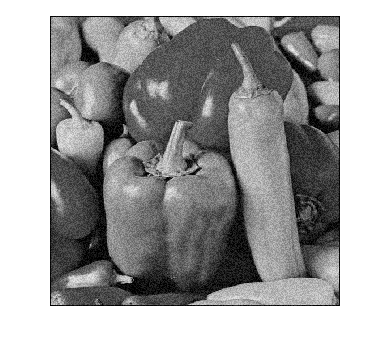

dist2 = conv2(im2double(pg),f,'same');

imshow(dist1)

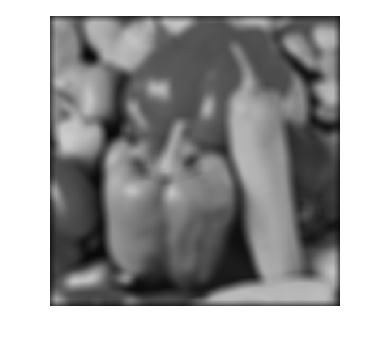

imshow(dist2)


mysnr(im2double(pg), im2double(pg) - dist1)

ans = 18.2165

mysnr(im2double(pg), im2double(pg) - dist2)

ans = 14.9577


ssim(dist1,im2double(pg))

ans = 0.4344

ssim(dist2,im2double(pg))

ans = 0.6773

function d1 = distort1(d1)
    for i = 2:511
        % even number
        if mod(i,2) == 0
            d1(2:511,i) = d1(2:511,i) + 0.1;
        else
            d1(2:511,i) = d1(2:511,i) - 0.1;
        end
    end
end

function d1 = distort2(d1)
    for i = 2:511
        % even number
        if i <= 255
            d1(i,2:511) = d1(i,2:511) + 0.1;
        else
            d1(i,2:511) = d1(i,2:511) - 0.1;
        end
    end
end


function res = SCIELAB_STD(sampPerDeg, c)
    c_xyz = rgb2xyz(c);
    temp = scielab(sampPerDeg, c_xyz);
    res = std2(temp(:,:,1)) + std2(temp(:,:,2)) + std2(temp(:,:,3));
end